# 前日までの勝率または得点割合から試合結果を予測する

## 2000年以降の全シーズンについて二つの指標(勝率，得失点割合)それぞれで予測し，予測性能を比較する．

### 訓練データをさかのぼる日数を変えて検証する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;tic

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');
seasonStartYearVals=unique(tbl_results.SeasonStartYear);
trainingDataDurationVals=(30:30:240)';
parameterVals=[];

予測性能を保存する変数を用意する

PredictedMatches=[];    %予測対象の試合数
CorrectsByWins=[];      %勝率で予測した予測正解数
CorrectsByScoreRatio=[];    %得点割合で予測した予測正解数

シーズン開始年，および訓練データをさかのぼる日数を指定しそれぞれについて処理を行う．

for seasonStartYearVal=seasonStartYearVals'
    seasonStartYearVal
    toc
    for trainingDataDurationVal=trainingDataDurationVals'
        parameterVals=[parameterVals; seasonStartYearVal trainingDataDurationVal];
        ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
        tbl_teams_tmp=tbl_teams(ind,:);

必要な列をあらかじめ追加しておく

        WinRatio=zeros(size(tbl_teams_tmp,1),1);
        ScoreRatio=zeros(size(tbl_teams_tmp,1),1);
        RankByWins=zeros(size(tbl_teams_tmp,1),1);
        RankByScoreRatio=zeros(size(tbl_teams_tmp,1),1);
        tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio, RankByWins, RankByScoreRatio);
        numTeams=size(unique(tbl_teams_tmp.TeamName),1);

予測対象の開始日を求める

        ind = tbl_results.SeasonStartYear==seasonStartYearVal;
        seasonStartDate=min(tbl_results.Date(ind));
        predictionStartDate=seasonStartDate+days(31);

テスト用(test)の試合結果の表を作る

        ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
            & tbl_results.Date>=predictionStartDate;
        tbl_results_test=tbl_results(ind,:);

予測対象の日付一覧を作る

        predictionDates=unique(tbl_results_test.Date);
        PredictionByWin=[]; %予測結果
        PredictionByScoreRatio=[]; %予測結果
        ActualWin=[];   %実際の結果

予測対象日ごとに対象試合を選び，予測する

        for predictionDate=predictionDates'

予測対象日の試合のみを含む表を抽出する

            tbl_results_test_tmp=tbl_results_test(tbl_results_test.Date==predictionDate,:);

同一シーズンかつ予測対象以前の指定した日数の試合結果を抽出する

            ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
                & tbl_results.Date>predictionDate-days(trainingDataDurationVal) ...
                & tbl_results.Date<predictionDate;
            tbl_results_train=tbl_results(ind,:);

勝，負試合数，および得失点を集計する

集計用の変数を準備する

            Wins=zeros(size(tbl_teams_tmp,1),1);
            Loses=zeros(size(tbl_teams_tmp,1),1);
            ScoresFor=zeros(size(tbl_teams_tmp,1),1);
            ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

            for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

                TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
                TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

                ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
                ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
                ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
                ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

                if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
                    Wins(TeamANum)=Wins(TeamANum)+1;
                    Loses(TeamBNum)=Loses(TeamBNum)+1;
                elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
                    Loses(TeamANum)=Loses(TeamANum)+1;
                    Wins(TeamBNum)=Wins(TeamBNum)+1;
                end
            end

勝率，得点割合を更新する

            WinRatio=Wins./(Wins+Loses);
            ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
            tbl_teams_tmp.WinRatio=WinRatio;
            tbl_teams_tmp.ScoreRatio=ScoreRatio;

勝率→得失点割合の優先順でソートし，その順位を更新する．

            tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
            RankByWins=(1:size(tbl_teams_tmp,1))';
            tbl_teams_tmp.RankByWins=RankByWins;


得失点割合→勝率の優先順でソートし，その順位を更新する．

            tbl_teams_tmp=sortrows(tbl_teams_tmp,{'ScoreRatio','WinRatio'},'descend');
            RankByScoreRatio=(1:size(tbl_teams_tmp,1))';
            tbl_teams_tmp.RankByScoreRatio=RankByScoreRatio;

予測対象1試合ずつに対し，実際の勝敗と予測勝敗を記録する

            for n1=1:size(tbl_results_test_tmp,1)
                if tbl_results_test_tmp.HomeScore(n1)>tbl_results_test_tmp.AwayScore(n1)
                    ActualWin=[ActualWin;1];    %ホーム勝利を1と定義する
                else
                    ActualWin=[ActualWin;0];
                end

                TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test_tmp.Home(n1));
                TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test_tmp.Away(n1));
                TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
                TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
                if TeamARank<TeamBRank
                    PredictionByWin=[PredictionByWin;1];
                else
                    PredictionByWin=[PredictionByWin;0];
                end

                TeamARank=tbl_teams_tmp.RankByScoreRatio(TeamANum);
                TeamBRank=tbl_teams_tmp.RankByScoreRatio(TeamBNum);
                if TeamARank<TeamBRank
                    PredictionByScoreRatio=[PredictionByScoreRatio;1];
                else
                    PredictionByScoreRatio=[PredictionByScoreRatio;0];
                end

            end
        end

予測正解を判定する．

        isPredictionCorrectByWins= ActualWin==PredictionByWin;
        isPredictionCorrectByScoreRatio= ActualWin==PredictionByScoreRatio;

予測正解率を算出する

        predictionAccuracyByWin=mean(isPredictionCorrectByWins);
        predictionAccuracyByScoreRatio=mean(isPredictionCorrectByScoreRatio);

予測正解数などを保存する

        PredictedMatches=[PredictedMatches;size(tbl_results_test,1)];
        CorrectsByScoreRatio=[CorrectsByScoreRatio; sum(isPredictionCorrectByScoreRatio)];
        CorrectsByWins=[CorrectsByWins; sum(isPredictionCorrectByWins)];
    end
end

seasonStartYearVal = 2000

経過時間は 0.086962 秒です。


結果を保存する

save('NBAPredictionByDate05.mat')

図示する

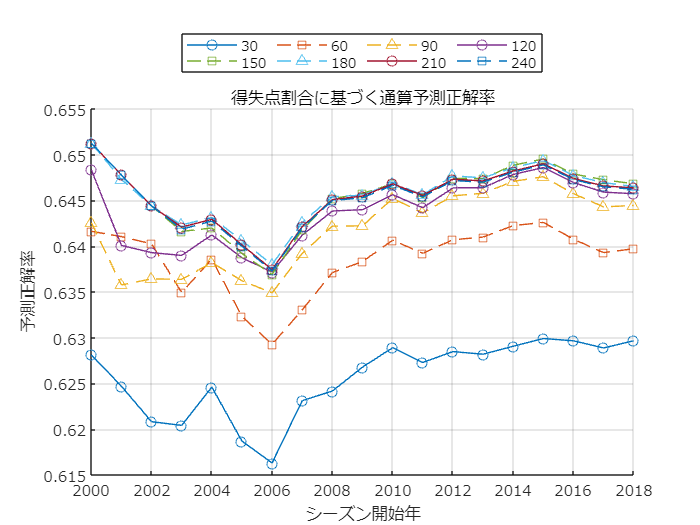

figure;
hold on;grid on;
for trainingDataDurationVal=trainingDataDurationVals'
    ind = parameterVals(:,2)==trainingDataDurationVal;
    plot(parameterVals(ind,1), cumsum(CorrectsByScoreRatio(ind))./cumsum(PredictedMatches(ind)));
end
ax=gca;
mylinestyles = ["-o"; "--s"; "--^"];
ax.LineStyleOrder = mylinestyles;
ax.LineStyleCyclingMethod = "withcolor";
set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('予測正解率');
legend(string(trainingDataDurationVals),'Location','northoutside','Orientation','horizontal','NumColumns',4);
title('得失点割合に基づく通算予測正解率')
hold off
exportgraphics(gcf,'fig_NBAPredictionCumSumByDateByWins05.pdf');

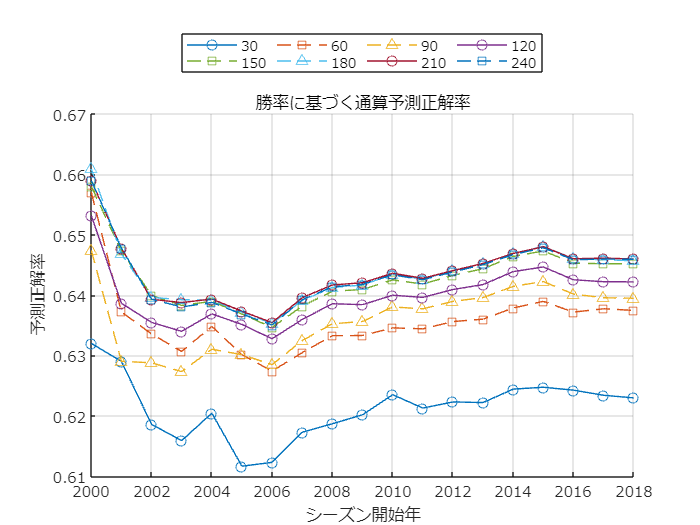

figure;
hold on;grid on;
for trainingDataDurationVal=trainingDataDurationVals'
    ind = parameterVals(:,2)==trainingDataDurationVal;
    plot(parameterVals(ind,1), cumsum(CorrectsByWins(ind))./cumsum(PredictedMatches(ind)));
end
ax=gca;
mylinestyles = ["-o"; "--s"; "--^"];
ax.LineStyleOrder = mylinestyles;
ax.LineStyleCyclingMethod = "withcolor";
set(gca,'fontname','メイリオ');
xlabel('シーズン開始年');ylabel('予測正解率');
legend(string(trainingDataDurationVals),'Location','northoutside','Orientation','horizontal','NumColumns',4);
title('勝率に基づく通算予測正解率')
hold off
exportgraphics(gcf,'fig_NBAPredictionCumSumByDateByScoreRatio05.pdf');